1 - koło

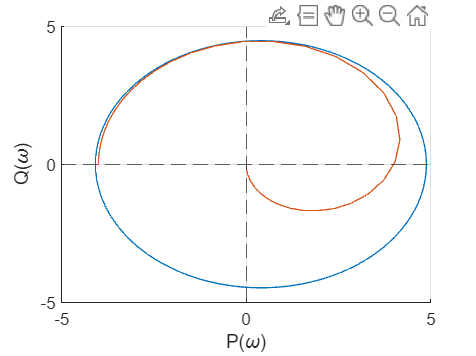

clear all;
s = tf('s');
G = 4*(1-5*s)/((1+3*s)*(1+2*s));
G = -G;
m1 = [-0.2 -0.34 -0.4];
m2 = [0.25 0.4 0.55];
f = @(m1 ,m2, P, Q) 1 - P.*(m1 + m2) + m1*m2*(P.^2 + Q.^2);

[P, Q, w] = nyquist(G);

m1 = -0.245;
m2 = 0.205;
p1 = 1/m1;
p2 = 1/m2;
figure(); hold on; grid on;
circle((p2 - p1)/2 + p1, 0, (p2 - p1)/2);
plot(P(1, :) , Q(1, :));
yline(0, '--');
xline(0, '--');


xlabel("P(\omega)"); ylabel("Q(\omega)"); hold off;


licz = cell2mat(G.Numerator(1,:));
mian = cell2mat(G.Denominator(1,:));
[A, b, c, d] = tf2ss(licz, mian);
m0 = 0;
Z = A + m0 * b*c;
eig(Z)

ans =    -0.5000
   -0.3333


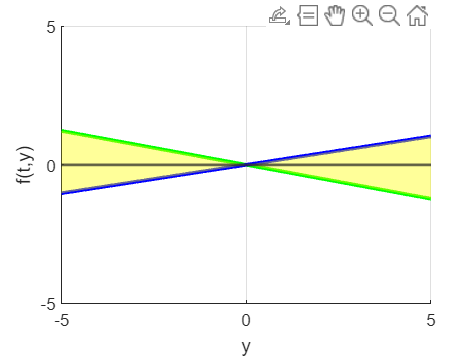


x = linspace(-5, 5, 100);
s1 = x.*m1;
s2 = x.*m2;
figure; hold on;
yline(0, "LineWidth", 1.5);
plot(x, s1, 'g', 'LineWidth', 2);
plot(x, s2, 'b', 'LineWidth', 2);
x2 = [x, fliplr(x)];
%legend("f(t,y) = m1 \cdot y", "f(t,y) = m2 \cdot y");
inBetween = [s1, fliplr(s2)];
fill(x2, inBetween, 'yellow', "FaceAlpha", 0.4, "EdgeColor", "none");
grid on;
xlabel("y");
ylabel("f(t,y)")
axis([-5 5 -5 5])
hold off;

1 - popow

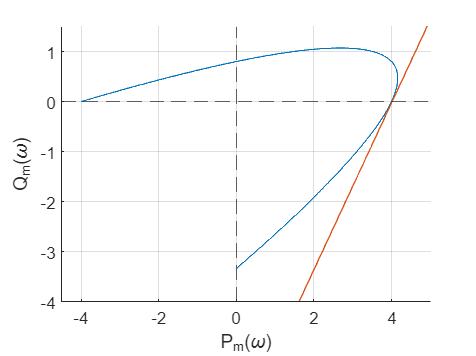

Licz=[20 -4]; %ujemna transmitancja wprowadzona
Mian=[6 5 1];
w = 0:0.001:100;
[P,Q,w]=nyquist(Licz, Mian, w);
figure; hold on; grid on;
P_m = P; Q_m = w.*Q;
plot(P_m, Q_m); % transmitancja zmodyfikowana
xlabel('P_{m}(\omega)');
ylabel('Q_{m}(\omega)');
% prosta P_m(w) - q*Q_m(w) - 1/m = 0
% % Transmitancja operatorowa jako funkcja symboliczna
% Go_s(s) = (20 * s - 4) / (6 * s^2 + 5 * s + 1);
% % Transmitancja widmowa
% Gw = Go_s(1j*w);
% % Częsc rzeczywista transmitancji widmowej
% P(w) = real(Gw);
% % Czesc urojona transmitancji widmowej
% Q = imag(Gw);

m = 0.249;
q = 0.6;
f = @(x) (1/m - x) / (-q);
fplot(f)
axis([-4.5 5 -4 1.5])
yline(0, '--');
xline(0, '--');
hold off;

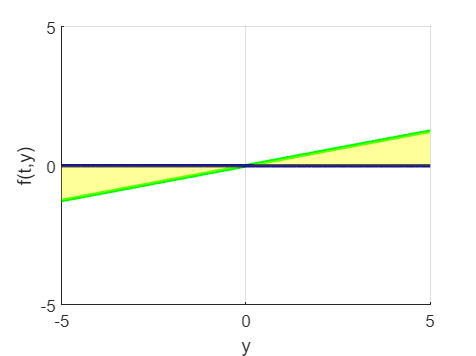


x = linspace(-5, 5, 100);
s1 = x.*m;
s2 = x.*0;
figure; hold on;
yline(0, "LineWidth", 1.5);
plot(x, s1, 'g', 'LineWidth', 2);
plot(x, s2, 'b', 'LineWidth', 2);
x2 = [x, fliplr(x)];
inBetween = [s1, fliplr(s2)];
fill(x2, inBetween, 'yellow', "FaceAlpha", 0.4, "EdgeColor", "none");
grid on;

xlabel("y");
ylabel("f(t,y)");
axis([-5 5 -5 5])
hold off;

2 - koło

A = [-2 1 0; -1 0 1; -1 0 0];
b = [-1; 0; 0];
c = [1 0 0];
d = 0;

[licz, mian] = ss2tf(A, b, c, d);
w = 0:0.001:100;
G = tf(licz, mian)

G =
 
         -s^2
  -------------------
  s^3 + 2 s^2 + s + 1
 
Continuous-time transfer function.
Model Properties


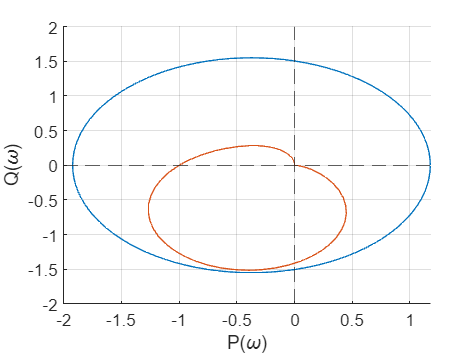


[P, Q, w] = nyquist(G);

m1 = -0.52;
m2 = 0.85;
p1 = 1/m1;
p2 = 1/m2;
figure(); hold on; grid on;
circle((p2 - p1)/2 + p1, 0, (p2 - p1)/2);
plot(P(1, :) , Q(1, :));
yline(0, '--');
xline(0, '--');


xlabel("P(\omega)"); ylabel("Q(\omega)"); hold off;


licz = cell2mat(G.Numerator(1,:));
mian = cell2mat(G.Denominator(1,:));
[A, b, c, d] = tf2ss(licz, mian);
m0 = 0;
Z = A + m0 * b*c;
eig(Z)

ans =   -1.7549 + 0.0000i
  -0.1226 + 0.7449i
  -0.1226 - 0.7449i


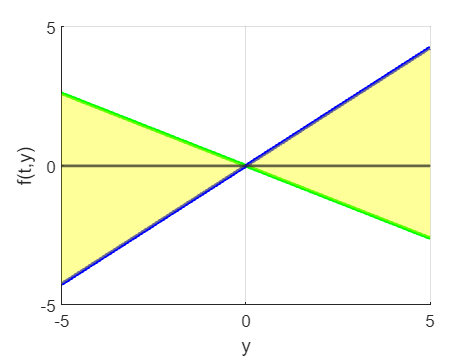


x = linspace(-5, 5, 100);
s1 = x.*m1;
s2 = x.*m2;
figure; hold on;
yline(0, "LineWidth", 1.5);
plot(x, s1, 'g', 'LineWidth', 2);
plot(x, s2, 'b', 'LineWidth', 2);
x2 = [x, fliplr(x)];
%legend("f(t,y) = m1 \cdot y", "f(t,y) = m2 \cdot y");
inBetween = [s1, fliplr(s2)];
fill(x2, inBetween, 'yellow', "FaceAlpha", 0.4, "EdgeColor", "none");
grid on;
xlabel("y");
ylabel("f(t,y)")
axis([-5 5 -5 5])
hold off;

2 - popow

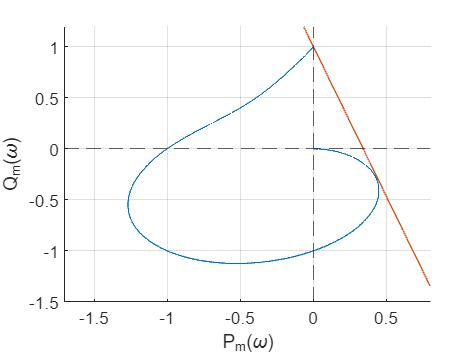

A = [-2 1 0; -1 0 1; -1 0 0];
b = [-1; 0; 0];
c = [1 0 0];
d = 0;

[licz, mian] = ss2tf(A, b, c, d);
w = 0:0.001:100;

[P,Q,w]=nyquist(licz, mian, w);

figure; hold on; grid on;
P_m = P; Q_m = w.*Q;
plot(P_m, Q_m); % transmitancja zmodyfikowana
xlabel('P_{m}(\omega)');
ylabel('Q_{m}(\omega)');

m = 2.93;
q = -0.34;
f = @(x) (1/m - x) / (-q);
fplot(f)
axis([-1.7 0.8 -1.5 1.2])
yline(0, '--');
xline(0, '--');
hold off;

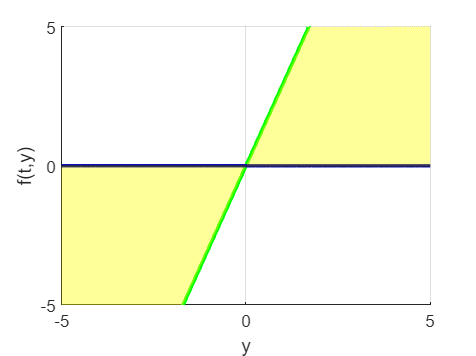


x = linspace(-5, 5, 100);
s1 = x.*m;
s2 = x.*0;
figure; hold on;
yline(0, "LineWidth", 1.5);
plot(x, s1, 'g', 'LineWidth', 2);
plot(x, s2, 'b', 'LineWidth', 2);
x2 = [x, fliplr(x)];
inBetween = [s1, fliplr(s2)];
fill(x2, inBetween, 'yellow', "FaceAlpha", 0.4, "EdgeColor", "none");
grid on;

xlabel("y");
ylabel("f(t,y)");
axis([-5 5 -5 5])
hold off;

function h = circle(x,y,r)
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit);
end